# Maximise the MATLAB Peaks Function

## Section 1.0 - Set Up

If the "Random" option is selected from the drop down menu on line 4, then a space-filling design ( Sobol sequence generator) is generated of the size selected in the edit box on line 9 of the code. Alternatively, if the "Fixed" option is selected from the drop down menu, then a constant design is used. In either case, we assume the form of ***f(x)*** is unknown, and iid normally distributed noise with a standaard deviation of 0.2 is added to the data - mimicing the act of sampling by measurement. Thus, even using the "Fixed" design, different results will be generated each time the live script is run.

clc
clear
%---------------------------------------------------------------------
% Select the acquisition function
%---------------------------------------------------------------------
AcqFcn = "aei";
[ X, Y, Z ] = peaks( 40 );
Selection = "Random";
if contains( "Random", Selection )
    %-----------------------------------------------------------------
    % Generate 2-D Sobol sequence - space-filling design
    %-----------------------------------------------------------------
    DesignSize = 25;
    H = sobolset( 2 );
    Hs = scramble( H, "MatousekAffineOwen" );
    D = net( Hs, DesignSize );
    %-----------------------------------------------------------------
    % Map the design to the interval [ -3, 3 ]
    %-----------------------------------------------------------------
    D = [ 6, 6 ] .* ( D ) - [ 3, 3];
else
    %-----------------------------------------------------------------
    % Use fixed data leading to the global maximum
    %-----------------------------------------------------------------
    D = [-2.888	2.182	-1.084	0.197	-1.742	2.541	-0.731	1.338	-2.507	1.802	-1.489	0.601	-2.145	2.946	-0.351	0.957	-2.706	2.000	-0.892	0.004
         -1.253	0.789	2.817	-2.554	0.341	-0.618	-1.591	2.040	1.746	-2.219	-0.168	0.468	-2.661	2.376	1.426	-0.939	1.093	-1.370	-2.343	2.792].';
end
x = D( :, 1 );
y = D( :, 2 );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
Sigma = 0.2;

Sigma =           0.2

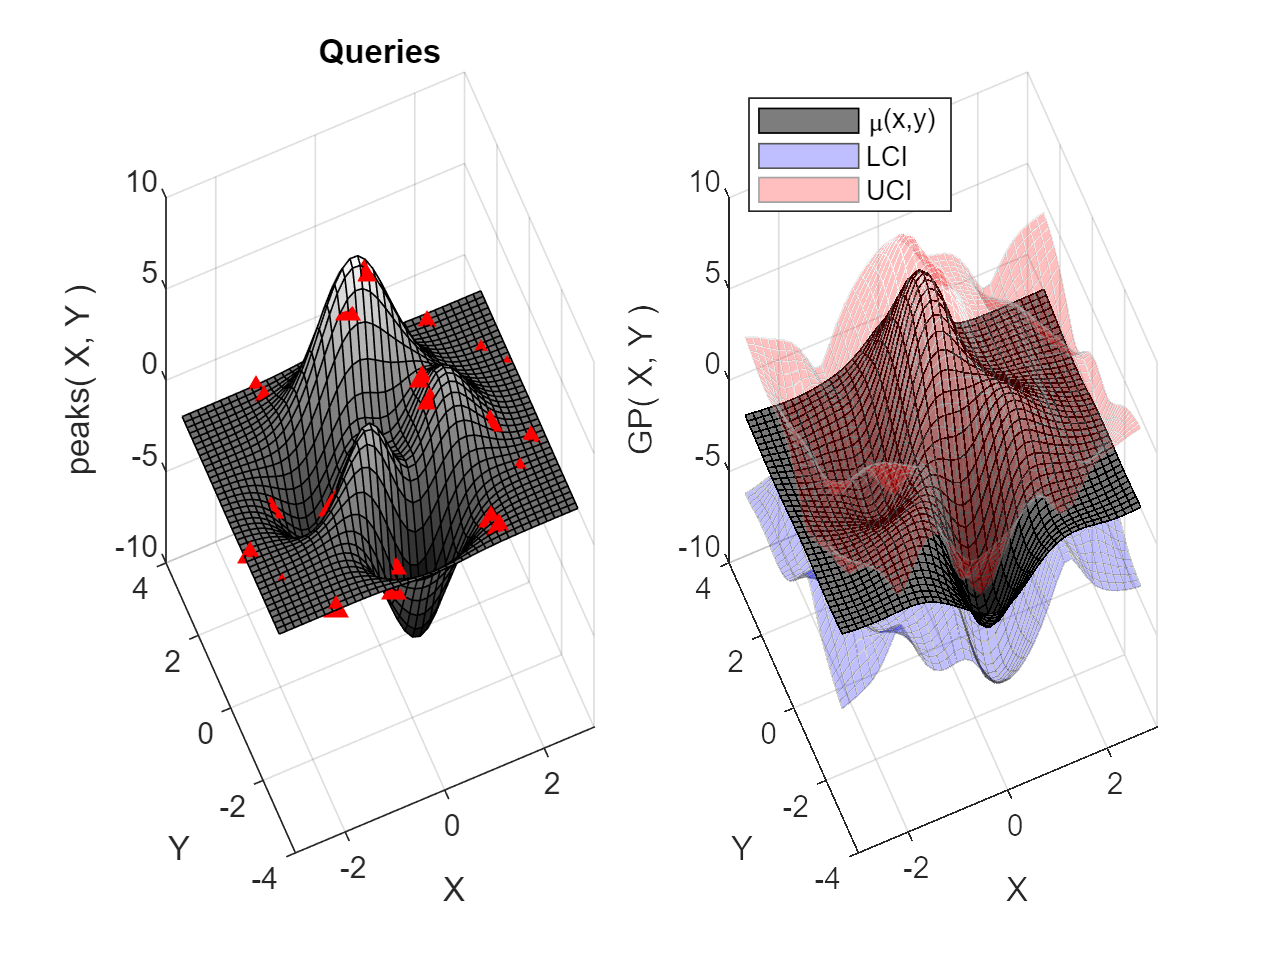

z = peaks( x, y ) +  Sigma*randn( size(x) );
plot3( x, y, z, 'r^', 'MarkerFacecolor', 'red');
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
title( Ax, "Queries" );
B = bayesOpt( "gpr", AcqFcn );
%-----------------------------------------------------------------
% Define the data coding: [-3, 3] --> [ -1, 1]
%-----------------------------------------------------------------
B = B.conDataCoding( [-3, -3 ], [ 3, 3 ] );
%-----------------------------------------------------------------
% Set the training data and train the model
%-----------------------------------------------------------------
B = B.setTrainingData( [x, y], z );   
%-----------------------------------------------------------------
% Plot the predictions
%-----------------------------------------------------------------
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

I = 0;

## SECTION 2.0 - Define bayesOpt Object & Perform Algorithm Iteration 1.0

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", B.Xlo, "ub", B.Xhi );

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -1.181313e-01    0.000e+00    5.493e-01
    1       9   -1.550913e-01    0.000e+00    1.338e-01    7.127e-02
    2      12   -1.742707e-01    0.000e+00    1.082e-01    7.125e-02
    3      17   -1.901380e-01    0.000e+00    6.589e-02    1.407e-01
    4      20   -1.914980e-01    0.000e+00    2.674e-02    5.739e-02
    5      23   -1.915368e-01    0.000e+00    1.454e-02    1.878e-02
    6      26   -1.915818e-01    0.000e+00    1.371e-03    8.544e-03
    7      29   -1.915820e-01    0.000e+00    1.467e-04    2.365e-04
    8      32   -1.915820e-01    0.000e+00    2.730e-06    8.646e-05
    9      35   -1.915820e-01    0.000e+00    1.467e-06    1.342e-06
   10      38   -1.915820e-01    0.000e+00    5.595e-08    9.744e-07

Local minimum found that satisfies the cons

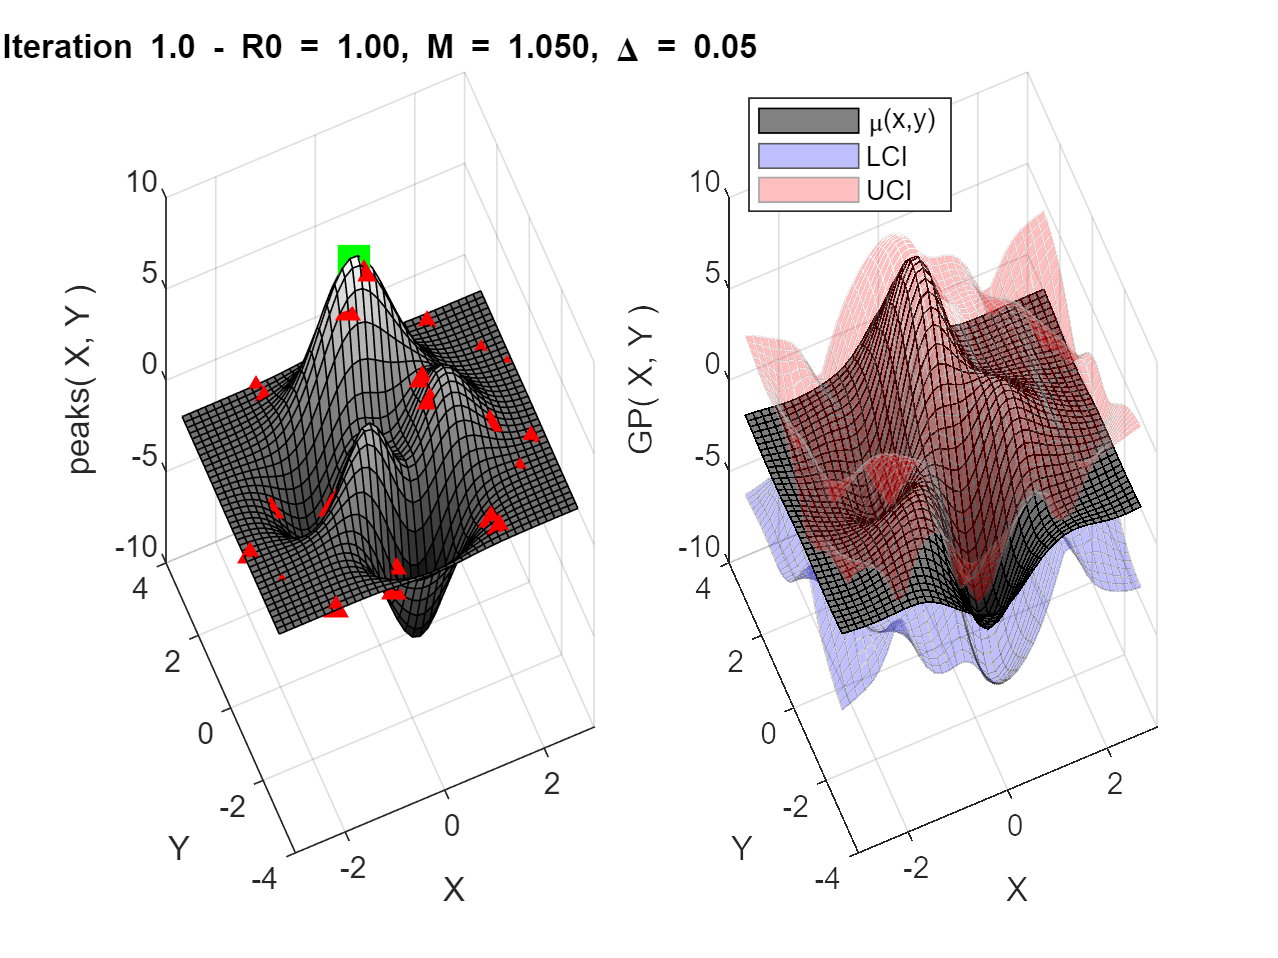

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

## SECTION 3.0 - Subsequent Iterations

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", [ -3, -3], "ub", [ 3, 3 ]);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -1.908684e-02    0.000e+00    9.021e-02
    1       7   -1.929730e-02    0.000e+00    1.250e-01    5.046e-02
    2      10   -2.143427e-02    0.000e+00    2.695e-03    3.915e-02
    3      13   -2.144131e-02    0.000e+00    6.805e-04    4.926e-03
    4      16   -2.144171e-02    0.000e+00    1.362e-04    8.252e-04
    5      19   -2.144172e-02    0.000e+00    6.272e-06    1.033e-04
    6      22   -2.144172e-02    0.000e+00    1.359e-06    1.421e-06
    7      25   -2.144172e-02    0.000e+00    8.863e-08    1.029e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

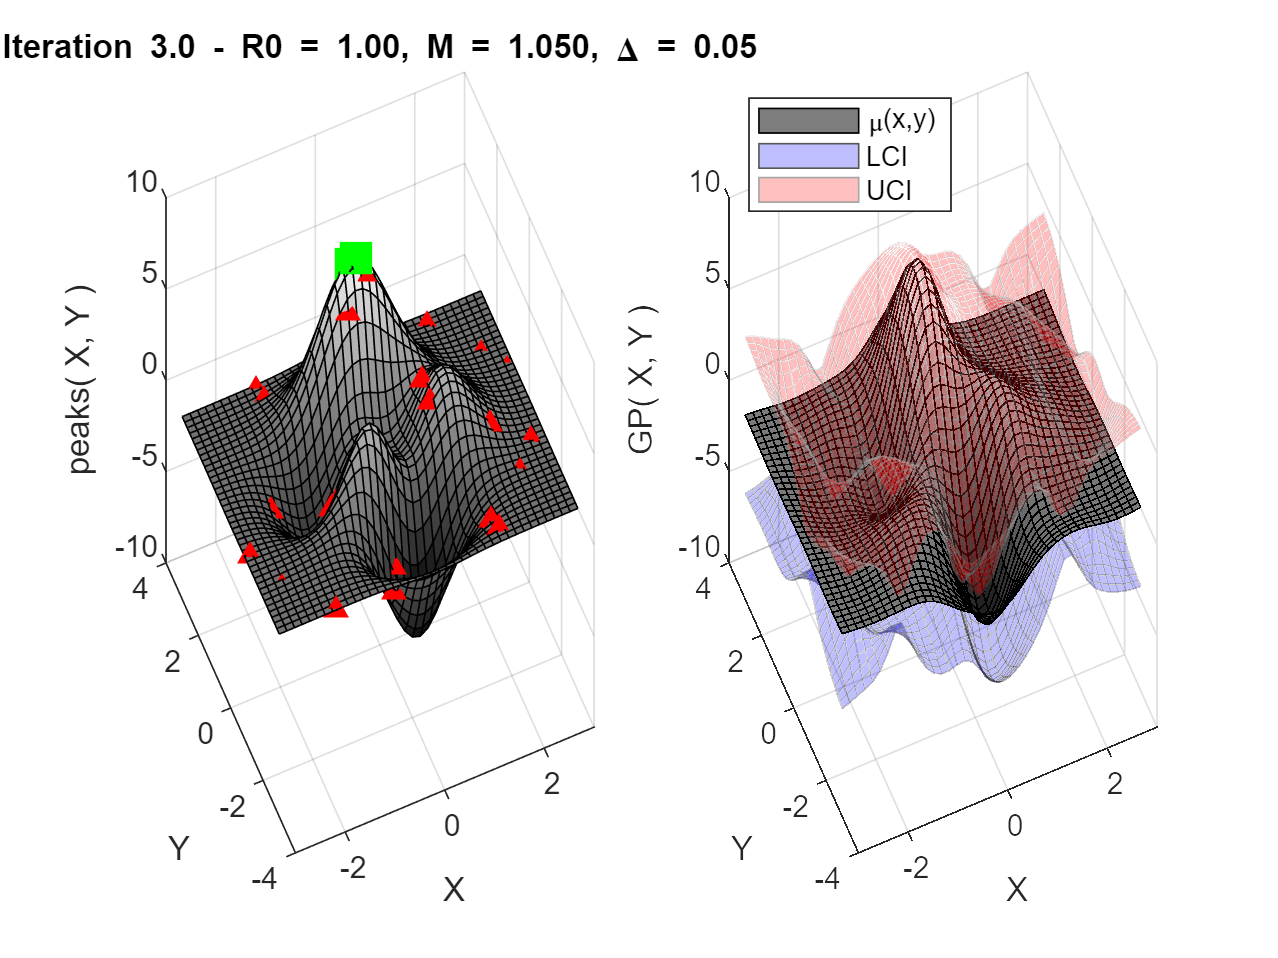

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );

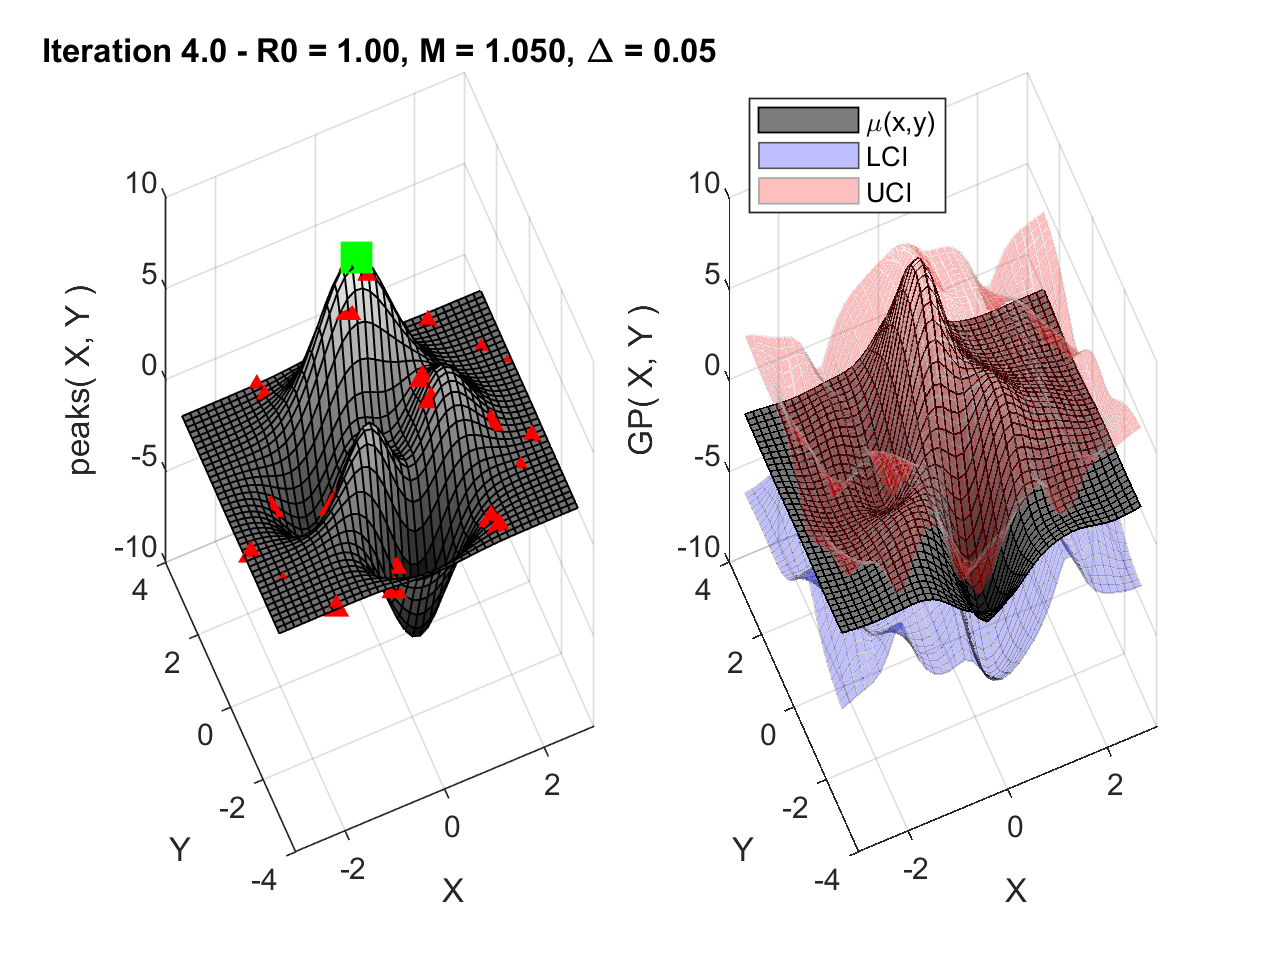

figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );